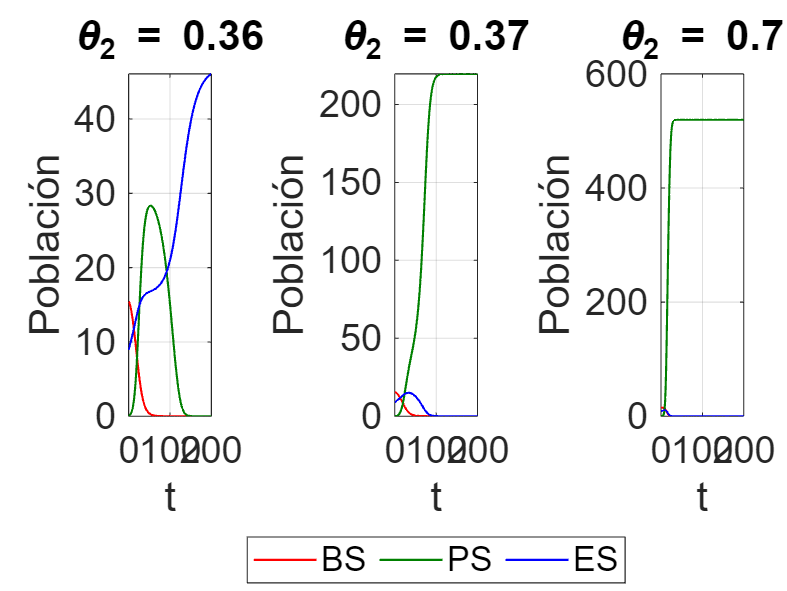

% Limpiar el espacio de trabajo, la ventana de comandos y cerrar figuras
clear;    
clc;     
close all;

% Parámetros del sistema
alpha1 = 0.00137;
beta1 = 0.07;
gamma1 = 0.01;
mu1 = 0.01;
alpha2 = 0.0011;
beta2 = 0.29;
gamma2 = 0.01;
mu2 = 0.01;
alpha3 = 0.001;
beta3 = 0.1;
tau = 0.0995;
C = 146.9;

% Condiciones iniciales
x0 = [15.4667; 0.0790; 8.9326]; % Ajusta según tu sistema
tspan = [0, 200];

% Vector de valores de eta con un máximo de 4 decimales
thetas2 = [0.36, 0.37, 0.7];

figure;
t = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:length(thetas2)
    theta2 = thetas2(i);

    sistema = @(t, x) [
        (alpha1 * x(1) * (C - x(1) - x(2) - x(3))) / (1 + gamma1 * x(3)) ...
            - x(1) * (beta1 + mu1 * x(3));
        (alpha2 * x(2) * (C - x(1) - x(2) - x(3)) * (1 + tau * x(1))) / (1 + gamma2 * x(3)) ...
            - x(2) * (beta2 + mu2 * x(3) - theta2);
        alpha3 * x(3) * (C - x(1) - x(2) - x(3)) - beta3 * x(3) ;
    ];

    [t_sim, x] = ode45(sistema, tspan, x0);

    nexttile;
    plot(t_sim, x(:,1), 'r','DisplayName', 'BS', 'LineWidth', 1); hold on;
    plot(t_sim, x(:,2), 'color', [0, 0.5, 0], 'DisplayName', 'PS', 'LineWidth', 1);
    plot(t_sim, x(:,3), 'b', 'DisplayName', 'ES', 'LineWidth', 1);
    title(['\theta_2 = ', num2str(theta2)]);
    xlabel('t'); ylabel('Población');
    grid on;

    ax = gca;
    ax.FontSize = 18;

end


% Eliminar leyendas anteriores si las hay
delete(findall(gcf, 'Type', 'legend'))
% Añadir leyenda global debajo
lgd = legend({'BS', 'PS', 'ES'}, 'Orientation', 'horizontal');
lgd.Layout.Tile = 'south';